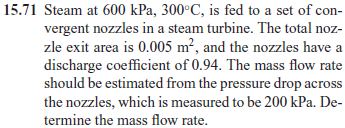

# classes

u = symunit;
steam = ig('Steam');

# inflow properties

% superheated steam tables
pi = 600*u.kPa;
Ti = 300*u.Celsius;
vi = 0.43437*u.m^3/u.kg;
hi = 3061.63*u.kJ/u.kg;
si = 7.3723*u.kJ/(u.kg*u.K);
Vi = 0;

# outflow properties

% superheated steam tables
pe = pi-200*u.kPa;
se = si;
Te = 143.63*u.Celsius;
ve = interp1([7.1706 7.3788], [0.53422 0.59512], double(removeUnits(si)))*u.m^3/u.kg;
ve_vpa = vpa(ve, 4)

$$ve\_vpa = 0.5932\,\frac{m^{3}}{\mathrm{kg}}$$

he = interp1([7.1706 7.3788], [2860.51 2964.16], double(removeUnits(si)))*u.kJ/u.kg;
he_vpa = vpa(he, 6)

$$he\_vpa = 2960.92\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$

Ae = 0.005*u.m^2;
% conservation of energy
syms Ve positive;
Ve = solve(hi+Vi^2/2 == he+Ve^2/2);
Ve = simplify(combine(Ve));
Ve_vpa = vpa(Ve, 5)

$$Ve\_vpa = 448.79\,\frac{m}{s}$$

# mass flow rate

cD = 0.94;
mdote = cD*Ae*Ve/ve;
mdote_vpa = vpa(mdote, 3)

$$mdote\_vpa = 3.56\,\frac{\mathrm{kg}}{s}$$